# LoopDetect Example

This script reproduce examples given in the manual and manuscript

**Resources:**

[1] LoopDetect MATLAB package: [https://de.mathworks.com/matlabcentral/fileexchange/81928-loopdetect/](https://de.mathworks.com/matlabcentral/fileexchange/81928-loopdetect/)

[2] Quick tutorial: [https://kabaum.gitlab.io/loopdetect_for_matlab/workflow_LoopDetect_Matlab.html](https://kabaum.gitlab.io/loopdetect_for_matlab/workflow_LoopDetect_Matlab.html)

[3] Glossary of functions: [https://kabaum.gitlab.io/loopdetect_for_matlab/](https://kabaum.gitlab.io/loopdetect_for_matlab/) 

## 0. Start

### 0.1. Cleaning the environment

clear; close all; clc;

### 0.2. Installation and import

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

## 1. First example

### 1.1. Loop characteristics

4 species, positive feedbacks. Firstly, we assigned 1 to all linear parameters.

s_star=[1,1,1,1]';
klin=ones(1,8); knonlin=[2.5,3];
loop_list=find_loops_vset(@(x)func_POSm4(1,x,klin,knonlin),s_star,10);
disp(loop_list{1})

        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 
    {[      1 1]}      1        -1 
    {[      2 2]}      1        -1 
    {[      3 3]}      1        -1 
    {[      4 4]}      1        -1 



first_loop=loop_list{1}.loop{1}

first_loop =      4     1     2     3     4


### 1.2. Solving the ODE model

Now, we assigned the parameters accordingly to the manuscript, attempt to reproduce the results.

%klin=[165,0.044,0.27,550,5000,78,4.4,5.1];
%knonlin=[0.3,2];

klin =[150, 0.04, 0.3, 500, 5000, 80, 4, 5];
knonlin=[0.3,2]

knonlin =     0.3000    2.0000


tspan = linspace(0, 13, 13001); 

% Add initial value. Previously: ones(1,4)
initial_values = [1,2,3,4];
%[t,sol]=ode15s(@(t,x)func_POSm4(t,x,klin,knonlin),[0,11], initial_values); % previous time=[0,50]

opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_POSm4(t,x,klin,knonlin), tspan, initial_values, opts);
s_star=sol(end,:); %the last point of the simulation is chosen

### 1.3. Calculating the Jacobian matrix

The functions `numerical_jacobian()` and `numerical_jacobian_complex()` provide numerical estimates of the Jacobian matrix of an ODE system at a chosen state vector $s_{\ast }$. They implement, respectively, a **finite-difference method using real perturbations** and the **complex-step method**, the latter offering higher accuracy due to the absence of subtractive cancellation errors (see Martins *et al*., 2003) and making use of MATLAB’s built-in support for complex arithmetic.

The function handle **f** (in the example derived from `func_POSm4`, the positive-feedback chain model of Baum *et al*., 2016) must refer to a function that returns the vector of time derivatives,


$$f_i \left(s\right)=\frac{\;{\textrm{dS}}_i }{\textrm{dt}}\ldotp$$


When used with `numerical_jacobian_complex()`, this function is required to depend **only** on the state variables. Any additional dependencies—such as model parameters—must be fixed beforehand so that $f$ effectively maps only the variable vector $s$ to its corresponding derivative vector.

%klin=[165,0.044,0.27,550,5000,78,4.4,5.1];
klin =[150, 0.04, 0.3, 500, 5000, 80, 4, 5];
knonlin=[0.3,2];
j_matrix=numerical_jacobian_complex(@(s)func_POSm4(1,s,klin,knonlin),...
s_star);
signed_jacobian=sign(j_matrix)

signed_jacobian =     -1     0     0    -1
     1    -1     0     1
     0     1    -1     0
     0     0     1    -1


### 1.4. Computing all feedback loops and useful functions for loop search

loop_list=find_loops(j_matrix)

loop_list = 6×3 table
        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 
    {[      1 1]}      1        -1 
    {[      2 2]}      1        -1 
    {[      3 3]}      1        -1 
    {[      4 4]}      1        -1 


Single loops can be examined by entering the corresponding entry.

for i=1:3
    disp(loop_list.loop{i})
end

     4     1     2     3     4

     4     2     3     4

     1     1



The function `loop_summary()` provides a convenient report on total number of loops, subdivided by their lengths and signs.

disp(loop_summary(loop_list))

                length_1    length_2    length_3    length_4
                ________    ________    ________    ________

    total          4           0           1           1    
    negative       4           0           0           1    
    positive       0           0           1           0    



One can filter the loop list for loops containing specific variables, for example the one with index 2:

noi = 2;
loops_with_node2=loop_list(...
    cellfun(@(z) ismember(noi,z),loop_list.loop),:)

loops_with_node2 = 3×3 table
        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 
    {[      2 2]}      1        -1 


Search a loop list for loops containing specific edges defined by the indices of the ingoing and outgoing nodes. This example returns the indices of all loops with a regulation of node 3 by node 2. These are only two here.

loop_edge_ind=find_edge(loop_list,2,3);
loops_with_edge_2_to_3=loop_list(loop_edge_ind,:)

loops_with_edge_2_to_3 = 2×3 table
        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 


for i=1:2
    disp(loops_with_edge_2_to_3.loop{i})
end

     4     1     2     3     4

     4     2     3     4



Saving and reading loop lists from files can be done using MATLAB's `save()` and `load()` functions. They keep the correct data format, but objects have to be retrieved from a struct.

save('loop_list_example.mat', 'loops_with_node2')
loaded_loops_with_node2=load('loop_list_example.mat')

loaded_loops_with_node2 = struct with fields:
    loops_with_node2: [3×3 table]


% access the loaded data table from the struct (might not be required
% in earlier MATLAB versions)
loaded_loops_with_node2.loops_with_node2

ans = 3×3 table
        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 
    {[      2 2]}      1        -1 


Reading and writing loop lists to tabular format can be performed via MATLAB's `writetable()` and `readtable()` functions. Here, we choose tabs as delimiters. Note that the formatting is lost.

writetable(loops_with_node2,'loop_list_example.txt','Delimiter','\t')
loops_with_node2_readin = readtable('loop_list_example.txt')

loops_with_node2_readin = 3×7 table
    loop_1    loop_2    loop_3    loop_4    loop_5    length    sign
    ______    ______    ______    ______    ______    ______    ____

      4         1          2         3         4        4        -1 
      4         2          3         4       NaN        3         1 
      2         2        NaN       NaN       NaN        1        -1 


### 1.5. Plots

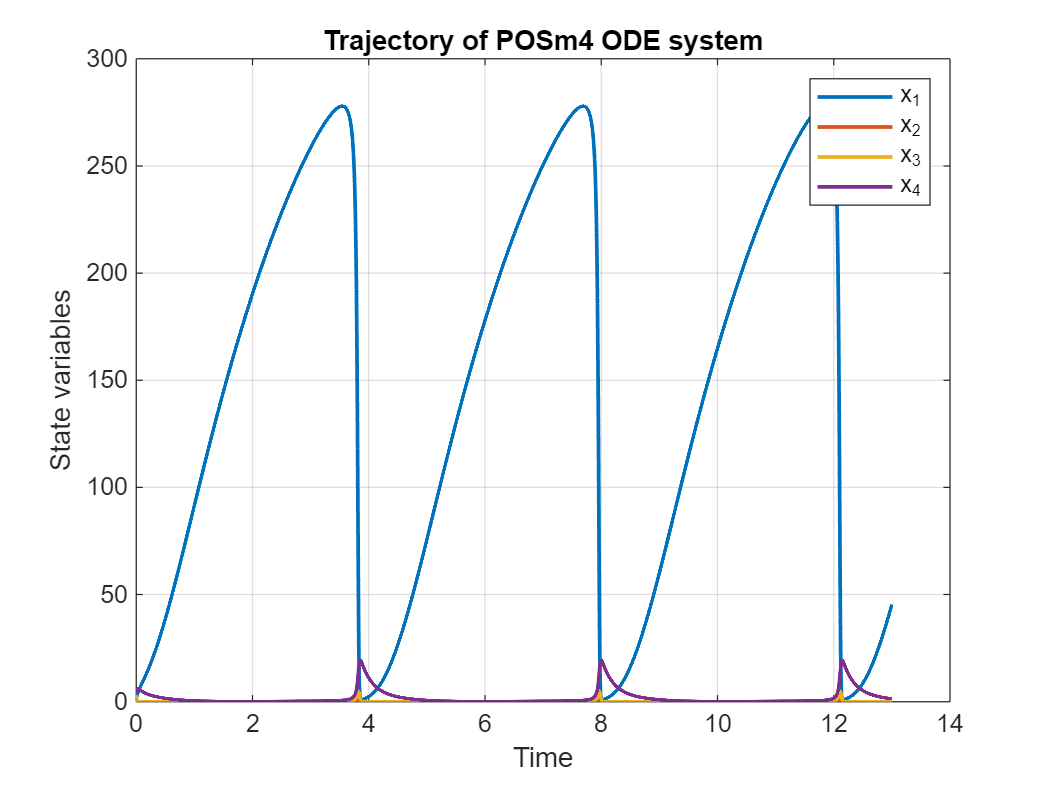

figure;
plot(t, sol, 'LineWidth', 1.5);
xlabel('Time');
ylabel('State variables');
title('Trajectory of POSm4 ODE system');
legend('x_1','x_2','x_3','x_4');
grid on;

Rescale y-axis to log-scale.

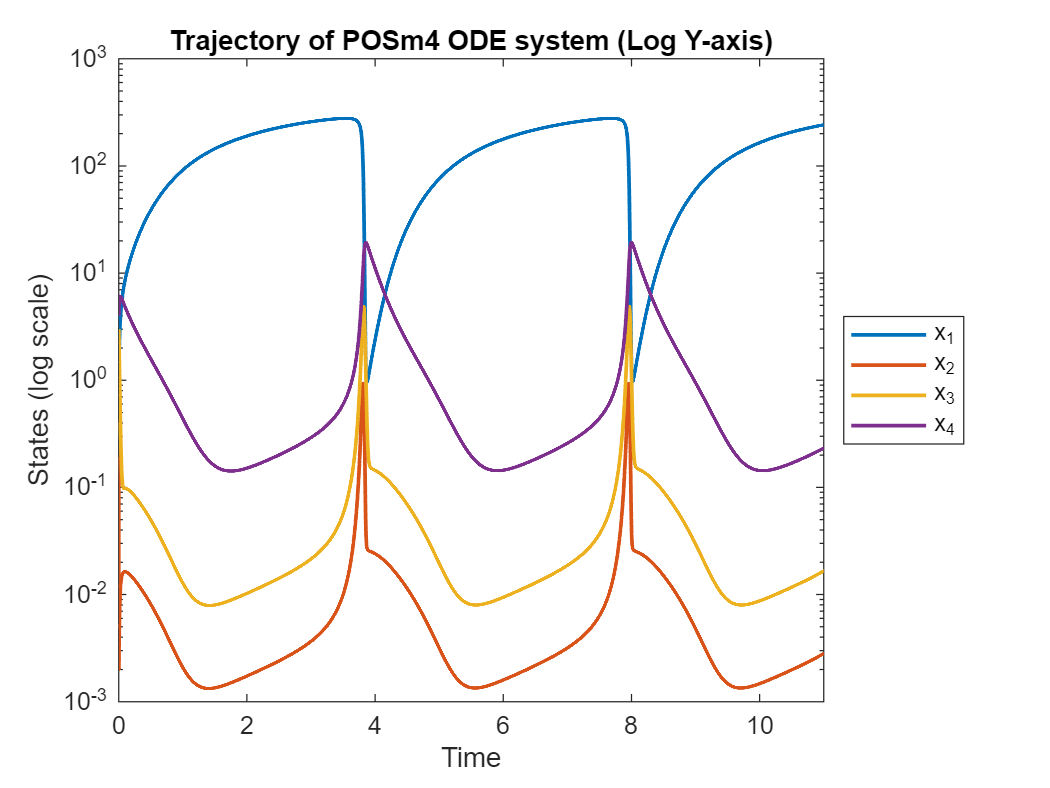

figure;
semilogy(t, sol, 'LineWidth', 1.5);
xlabel('Time');
ylabel('States (log scale)');
xlim([0,11]);
title('Trajectory of POSm4 ODE system (Log Y-axis)');
legend('x_1','x_2','x_3','x_4','Location','eastoutside'); % southeast

## 2. Second example

Calcium oscillation

function [dx] = func_gold90(t,x,klin,knonlin)
        dx=zeros(2,1);
        %J=jacob_gold90(t,x,klin,knonlin);
        dx(1)= klin(1)+klin(2)-klin(3)*x(1)^knonlin(4)/(knonlin(1)^knonlin(4)+x(1)^knonlin(4))+klin(4)*x(2)^knonlin(5)*x(1)^knonlin(6)/((knonlin(2)^knonlin(5)+x(2)^knonlin(5))*(knonlin(3)^knonlin(6)+x(1)^knonlin(6)))+klin(5)*x(2)-klin(6)*x(1);
        dx(2)=klin(3)*x(1)^knonlin(4)/(knonlin(1)^knonlin(4)+x(1)^knonlin(4))-klin(4)*x(2)^knonlin(5)*x(1)^knonlin(6)/((knonlin(2)^knonlin(5)+x(2)^knonlin(5))*(knonlin(3)^knonlin(6)+x(1)^knonlin(6)))-klin(5)*x(2);
    end

Initial values:

initial_conditions_calcium = [0.3920, 1.6456];
klin_calcium = [1, 7.3, 65, 500, 1, 10];
kn_calcium = [1, 2, 0.9];
n_calcium = [2, 2, 4];
knonlin_calcium = [1, 2, 0.9, 2, 2, 4]

knonlin_calcium =     1.0000    2.0000    0.9000    2.0000    2.0000    4.0000


time_points = linspace(0, 3, 31);

Solve:

opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_gold90(t,x,klin_calcium,knonlin_calcium), time_points, initial_conditions_calcium, opts);
s_star=sol(end,:); %the last point of the simulation is chosen

Visualize:

figure;
plot(t, sol, 'LineWidth', 1.5);
xlabel('Time');
ylabel('State variables');
title('Trajectory of POSm4 ODE system');
legend('x_1','x_2','x_3','x_4');

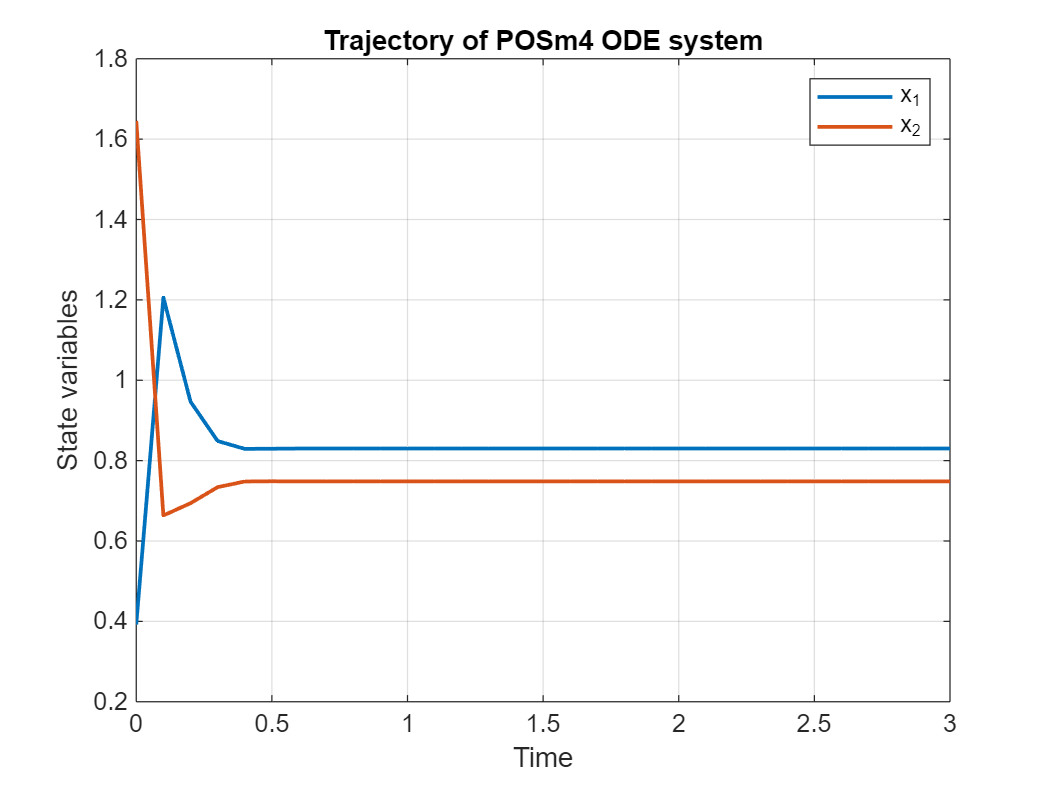

grid on;

## 5. Export *.mlx to *.html

path = export("MATLAB/test.mlx", "MATLAB/test.pdf")

path = 'MATLAB\test.pdf'

mdfile = export("MATLAB/test.mlx","MATLAB/test.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)

mdfile = 'MATLAB\test.md'